% target_id = 17;


target_id = id_list

target_id = 48

正在为 ID=48 生成可视化图像...


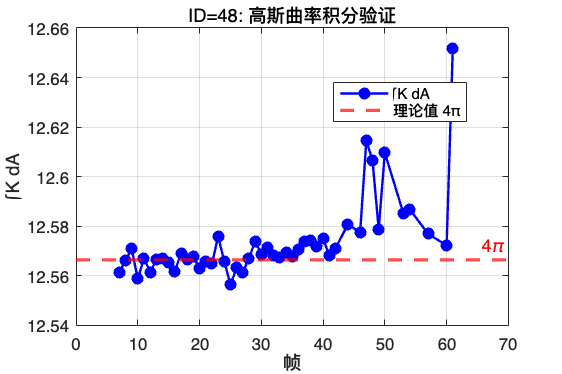

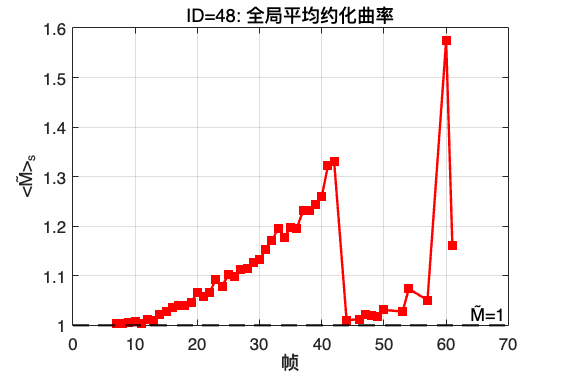

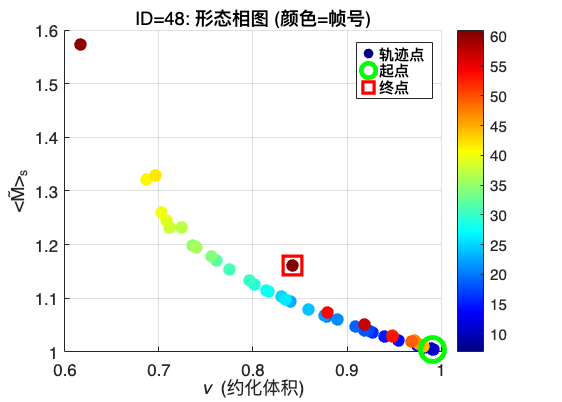

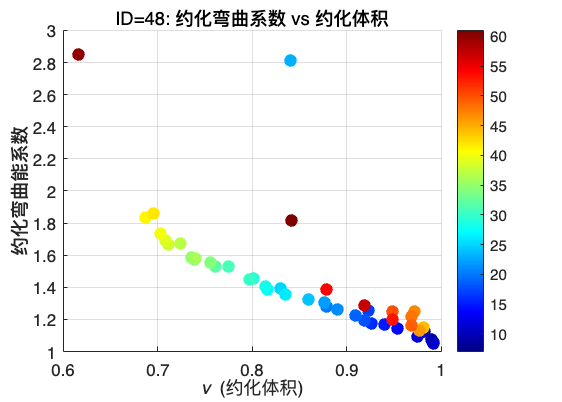

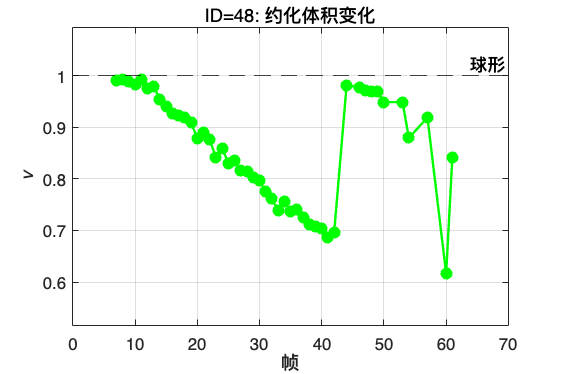

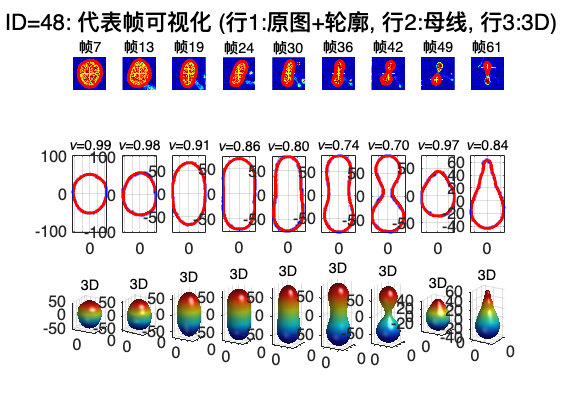

ID=48 的所有图像已保存至 ./Analysis_Images-1218-7-1




visualize_single_ID(AllResults, target_id, output_folder)



function visualize_single_ID(AllResults, target_id, output_folder)
% 可视化单个ID的完整分析结果
% 用法: visualize_single_ID(AllResults, 1, './Analysis_Images')
%
% 输入:
%   AllResults  - 包含所有分析结果的结构体
%   target_id   - 要可视化的ID编号
%   output_folder - 图像保存文件夹

    if nargin < 3
        output_folder = './Analysis_Images';
    end
    
    if ~exist(output_folder, 'dir')
        mkdir(output_folder);
    end
    
    % 检查ID是否有效
    if target_id > length(AllResults) || isempty(AllResults(target_id).ID)
        error('ID=%d 不存在或无有效数据', target_id);
    end
    
    R = AllResults(target_id);
    id = target_id;
    
    fprintf('正在为 ID=%d 生成可视化图像...\n', id);
    
    % 提取数据
    x_clean = R.Frames;
    V_clean = R.Volume_um3;
    S_clean = R.Surface_um2;
    nu_clean = R.Nu;
    M_clean = R.M_tilde;
    I_K_clean = R.I_Gauss;
    rb_clean = R.Rb;
    V_re_clean = (4/3) * pi * R.R_ve_um.^3;
    stored_data = R.StoredData;
    
    % 不再筛选，所有帧都有效
    nFrames = length(stored_data);
    valid = true(nFrames, 1);
    nu_array = nu_clean;  % 直接使用
    
    % %% --- 图1：体积与表面积 ---
    % fig1 = figure('Color', 'w', 'Position', [50, 100, 1000, 400]);
    % subplot(1,2,1);
    % plot(x_clean, V_clean, 'b-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
    % xlabel('帧'); ylabel('体积 (μm³)');
    % title('体积变化'); grid on;
    % subplot(1,2,2);
    % plot(x_clean, S_clean, 'r-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
    % xlabel('帧'); ylabel('表面积 (μm²)');
    % title('表面积变化'); grid on;
    % sgtitle(sprintf('ID=%d: 体积与表面积', id), 'FontSize', 14);
    % saveas(fig1, fullfile(output_folder, sprintf('ID%03d_Fig1_Volume_Surface.png', id)));
    % 
    %% --- 图2：高斯曲率验证 ---
    fig2 = figure('Color', 'w', 'Position', [100, 100, 600, 400]);
    plot(x_clean, I_K_clean, 'b-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
    hold on;
    yline(4*pi, 'r--', '4\pi', 'LineWidth', 2);
    xlabel('帧'); ylabel('∫K dA');
    title(sprintf('ID=%d: 高斯曲率积分验证', id));
    grid on; legend('∫K dA', '理论值 4π', 'Location', 'best');
    saveas(fig2, fullfile(output_folder, sprintf('ID%03d_Fig2_Gauss_Curvature.png', id)));
    
    %% --- 图3：约化曲率 ---
    fig3 = figure('Color', 'w', 'Position', [100, 100, 600, 400]);
    plot(x_clean, M_clean, 'r-s', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
    hold on;
    yline(1, 'k--', 'M̃=1', 'LineWidth', 1.5);
    xlabel('帧'); ylabel('<M̃>_s');
    title(sprintf('ID=%d: 全局平均约化曲率', id));
    grid on;
    saveas(fig3, fullfile(output_folder, sprintf('ID%03d_Fig3_Reduced_Curvature.png', id)));
    
    %% --- 图4：相图 (nu vs M) ---
    fig4 = figure('Color', 'w', 'Position', [100, 100, 700, 500]);
    scatter(nu_clean, M_clean, 60, x_clean, 'filled');
    colorbar; colormap(jet);
    xlabel('\nu (约化体积)'); ylabel('<M̃>_s');
    title(sprintf('ID=%d: 形态相图 (颜色=帧号)', id));
    grid on;
    hold on;
    plot(nu_clean(1), M_clean(1), 'go', 'MarkerSize', 15, 'LineWidth', 3);
    plot(nu_clean(end), M_clean(end), 'rs', 'MarkerSize', 15, 'LineWidth', 3);
    legend('轨迹点', '起点', '终点', 'Location', 'best');
    saveas(fig4, fullfile(output_folder, sprintf('ID%03d_Fig4_Phase_Diagram.png', id)));
    
    %% --- 图5：约化系数 vs nu ---
    fig5 = figure('Color', 'w', 'Position', [100, 100, 700, 500]);
    scatter(nu_clean, rb_clean, 60, x_clean, 'filled');
    colorbar; colormap(jet);
    xlabel('\nu (约化体积)'); ylabel('约化弯曲能系数');
    title(sprintf('ID=%d: 约化弯曲系数 vs 约化体积', id));
    grid on;
    saveas(fig5, fullfile(output_folder, sprintf('ID%03d_Fig5_Bending_vs_Nu.png', id)));
    
    %% --- 图6：约化体积时间序列 ---
    fig6 = figure('Color', 'w', 'Position', [100, 100, 600, 400]);
    plot(x_clean, nu_clean, 'g-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'g');
    xlabel('帧'); ylabel('\nu');
    title(sprintf('ID=%d: 约化体积变化', id));
    grid on;
    % 根据数据动态设置Y轴范围
    if ~isempty(nu_clean)
        y_min = max(0, min(nu_clean) - 0.1);
        y_max = min(1.5, max(nu_clean) + 0.1);
        ylim([y_min y_max]);
    end
    yline(1, 'k--', '球形');
    saveas(fig6, fullfile(output_folder, sprintf('ID%03d_Fig6_Nu_TimeSeries.png', id)));
    
    % %% --- 图7：实际体积 vs 等效体积 ---
    % fig7 = figure('Color', 'w', 'Position', [100, 100, 1000, 400]);
    % subplot(1,2,1);
    % plot(x_clean, V_clean, 'b-o', 'LineWidth', 1.5); hold on;
    % plot(x_clean, V_re_clean, 'r--s', 'LineWidth', 1.5);
    % legend('实际体积 V', '等效球体积 V_{re}', 'Location', 'best');
    % xlabel('帧'); ylabel('体积 (μm³)');
    % title('体积对比'); grid on;
    % subplot(1,2,2);
    % plot(x_clean, nu_clean, 'g-o', 'LineWidth', 1.5, 'MarkerFaceColor', 'g');
    % xlabel('帧'); ylabel('\nu');
    % title('约化体积'); grid on;
    % if ~isempty(nu_clean)
    %     y_min = max(0, min(nu_clean) - 0.1);
    %     y_max = min(1.5, max(nu_clean) + 0.1);
    %     ylim([y_min y_max]);
    % end
    % sgtitle(sprintf('ID=%d: 体积分析', id), 'FontSize', 14);
    % saveas(fig7, fullfile(output_folder, sprintf('ID%03d_Fig7_Volume_Comparison.png', id)));
    % 
    %% --- 图8：综合仪表板 ---
    % %% --- 图8：综合仪表板 ---
    % fig8 = figure('Color', 'w', 'Position', [50, 50, 1400, 900]);
    % 
    % subplot(2,3,1);
    % plot(x_clean, V_clean, 'b-o', 'LineWidth', 1.5);
    % xlabel('帧'); ylabel('V (μm³)'); title('体积'); grid on;
    % 
    % subplot(2,3,2);
    % plot(x_clean, S_clean, 'r-o', 'LineWidth', 1.5);
    % xlabel('帧'); ylabel('S (μm²)'); title('表面积'); grid on;
    % 
    % subplot(2,3,3);
    % plot(x_clean, nu_clean, 'g-o', 'LineWidth', 1.5);
    % xlabel('帧'); ylabel('\nu'); title('约化体积'); grid on;
    % if ~isempty(nu_clean)
    %     y_min = max(0, min(nu_clean) - 0.1);
    %     y_max = min(1.5, max(nu_clean) + 0.1);
    %     ylim([y_min y_max]);
    % end
    % 
    % subplot(2,3,4);
    % plot(x_clean, M_clean, 'm-o', 'LineWidth', 1.5);
    % xlabel('帧'); ylabel('<M̃>'); title('约化曲率'); grid on;
    % 
    % subplot(2,3,5);
    % plot(x_clean, I_K_clean, 'c-o', 'LineWidth', 1.5);
    % hold on; yline(4*pi, 'r--');
    % xlabel('帧'); ylabel('∫K dA'); title('高斯曲率积分'); grid on;
    % 
    % subplot(2,3,6);
    % scatter(nu_clean, M_clean, 50, x_clean, 'filled');
    % colorbar; xlabel('\nu'); ylabel('<M̃>'); title('相图'); grid on;
    % 
    % sgtitle(sprintf('ID=%d: 综合动力学分析 (总帧数: %d)', id, length(R.Frames)), 'FontSize', 16);
    % saveas(fig8, fullfile(output_folder, sprintf('ID%03d_Fig8_Dashboard.png', id)));
    % 
    %% --- 图9：代表性帧图像预览 ---
    % 所有帧都有效，直接使用索引
    valid_indices = 1:length(stored_data);
    num_samples = min(9, length(valid_indices));
    
    if num_samples > 0
        idx_samples = round(linspace(1, length(valid_indices), num_samples));
        
        fig9 = figure('Color', 'w', 'Position', [50, 50, 1400, 1000]);
        
        for k = 1:num_samples
            sample_idx = valid_indices(idx_samples(k));
            
            if sample_idx <= length(stored_data) && ~isempty(stored_data(sample_idx).img_gray)
                
                % 行1：原图+轮廓
                subplot(3, num_samples, k);
                img_show = imadjust(stored_data(sample_idx).img_gray);
                imshow(img_show); hold on;
                if ~isempty(stored_data(sample_idx).centroids_reg)
                    plot(stored_data(sample_idx).centroids_reg(:,1), ...
                         stored_data(sample_idx).centroids_reg(:,2), 'y+', 'MarkerSize', 8);
                end
                if ~isempty(stored_data(sample_idx).boundary)
                    plot(stored_data(sample_idx).boundary(:,2), ...
                         stored_data(sample_idx).boundary(:,1), 'r-', 'LineWidth', 2);
                end
                title(sprintf('帧%d', stored_data(sample_idx).frame), 'FontSize', 9);
                
                % 行2：母线重建
                subplot(3, num_samples, num_samples + k);
                if ~isempty(stored_data(sample_idx).x_rot)
                    plot(stored_data(sample_idx).x_rot, stored_data(sample_idx).z_rot, ...
                         'b.', 'MarkerSize', 2);
                    hold on;
                    if ~isempty(stored_data(sample_idx).r_f)
                        plot(stored_data(sample_idx).r_f, stored_data(sample_idx).z_f, ...
                             'r-', 'LineWidth', 2);
                        plot(-stored_data(sample_idx).r_f, stored_data(sample_idx).z_f, ...
                             'r-', 'LineWidth', 2);
                    end
                    axis equal; grid on;
                    if sample_idx <= length(nu_array) && ~isnan(nu_array(sample_idx))
                        title(sprintf('\\nu=%.2f', nu_array(sample_idx)), 'FontSize', 9);
                    else
                        title('母线', 'FontSize', 9);
                    end
                end
                
                % 行3：3D重建
                subplot(3, num_samples, 2*num_samples + k);
                if ~isempty(stored_data(sample_idx).r_f) && ~isempty(stored_data(sample_idx).z_f)
                    r_3d = stored_data(sample_idx).r_f;
                    z_3d = stored_data(sample_idx).z_f;
                    theta_3d = linspace(0, 2*pi, 60);
                    [Theta, Idx] = meshgrid(theta_3d, 1:length(r_3d));
                    X_3d = r_3d(Idx) .* cos(Theta);
                    Y_3d = r_3d(Idx) .* sin(Theta);
                    Z_3d = z_3d(Idx);
                    surf(X_3d, Y_3d, Z_3d, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
                    colormap(jet); axis equal; view(30, 20);
                    lighting gouraud; camlight;
                    title('3D', 'FontSize', 9);
                end
            end
        end
        
        sgtitle(sprintf('ID=%d: 代表帧可视化 (行1:原图+轮廓, 行2:母线, 行3:3D)', id), 'FontSize', 14);
        saveas(fig9, fullfile(output_folder, sprintf('ID%03d_Fig9_Representative_Frames.png', id)));
    end
    
    fprintf('ID=%d 的所有图像已保存至 %s\n', id, output_folder);
    
    % 可选：关闭所有图像窗口
    % close all;
end